# Lead-lag compensator design with Bode diagrams

This live script needs the control toolbox. Once profficient, students will probably find that the methods used in this script are mostly performed using sisotool. We also assume the students are already comfortable with the design procedures in the files: **lead_design_with_bode.mlx and lag_design_with_bode.mlx**

This script assumes the following block diagram with system G(s) and compensator M(s). 

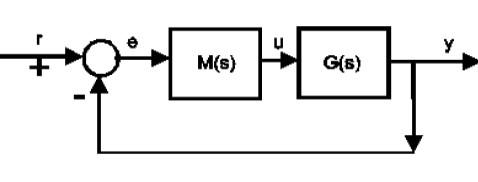

## Lead and Lag compensator reminders

The lead compensator is given as follows and is based on the two criteria: desired PM $\phi$ and desired bandwidth $w_c$ (cross over frequency). The offset is a consequence of  these two criteria and not managed. The full design process is in the file **lead_design_with_bode.mlx**

$\;M\left(s\right)$$=K\left(\frac{s+\frac{w_c }{\sqrt{r}}}{s+w_c \sqrt{r}}\right)$;        $1\le r\le 10$   

A lag compensator is based on the two criteria: desired PM $\phi$ and desired low frequency gain (typically a ramp error offset). The cross-over frequency $w_c$ falls out automatically from these two criteria. The full design process is in the file **lag_design_with_bode.mlx**

$M\left(s\right)\;=\;\;\;\;K\;\;\left(\frac{s+\frac{w_c }{10}}{s+\frac{w_c }{10p}}\right)$ ;                    $1\le p\le 10$.

## Why lead-lag compensator design?

Both lead and lag can satisfy only 2 criteria, and ignore the 3rd whereas typically there are 3 common criteria:

- phase margin (equivalently damping).

- offset.

- bandwidth/cross-over frequency .

By combining lead and lag, we add an additional degree of freedom (3 parameters* K, p, r*) and thus can meet all 3 criteria (assuming these are set sensibly).


$$M\left(s\right)\;=\;\;\;K\;\;\left(\frac{s+\frac{w_c }{10}}{s+\frac{w_c }{10p}}\right)$$

$$\left(\frac{s+\frac{w_c }{\sqrt{r}}}{s+w_c \sqrt{r}}\right)$$


## Fundamental approach to lead-lag design

- First use a standard lead design to meet the bandwidth $w_c$ and PM $\phi$requirements. This sets the parameters *K* and *r*.

- Second, add a lag component to improve the low frequency gain. Rather than being too fussy about a specific ramp error constant, we can talk about how much increase is wanted; this is given by parameter *p*.

## Section 2: Example of a simple lead-lag design using phase margin, bandwidth and low frequency gain criteria 

For this section, assume the system includes an integrator so that the offset to constant targets is zero. We want to design the parameters of the compensator M(s) so that we have a desirable phase margin, bandwidth and low frequency gain. The process can be systemised as follows into several key steps.

STEP 1: Specify the system and desired **CRITERIA**:  phase margin $\phi$ (equivalently damping ratio - see section 1a),  desired bandwidth (gain cross over frequency) $w_c$ and low frequency gain recovery *p*.  If these turn out to be poor or unreasonable choices it will be evident following the later design steps.

G=tf(1,[1 5 8 0]);
wc=2;
desiredPM = 60;
gainrecovery=5;
[gainGwc,phaseGwc] = bode(G,wc);

wmin=0.01;
wmax=6;
figure; clf
bode(G,{wmin,wmax});grid;hold on
plot([wmin,wmax],[-180+desiredPM]*[1 1],'r')
text(wmin*10,-180+desiredPM+10,'-180+\phi')
plot([wc,wc],[-180+desiredPM,-90],'g','linewidth',3)
text(wc*1.1,-180+desiredPM+15,'wc')


STEP 2: Determine how much phase change $\theta$ is required so that $\arg \left(G\left(jw_c \right)M\left(jw_c \right)\right)=-180+\phi$. Assume that $\arg \left(M\left(jw_c \right)\right)=\theta$  so this reduces to:  $\theta =-\arg \left(G\left(jw_c \right)\right)-180+\phi$ hence $\theta$ is required uplift at the gain cross over frequency $w_c$ to achieve the target PM. You need to ensure the required uplift is between about 10 and 55 degrees, or the required pole/zero ratio will be outside of bounds. **If the required uplift is too large, the desired bandwidth will need reducing.**

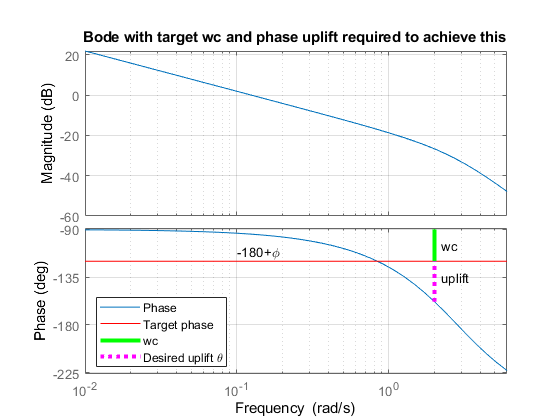

uplift = -180 - phaseGwc +desiredPM;
plot([wc,wc],[phaseGwc,-180+desiredPM],'m:','linewidth',3)
text(wc*1.1,-180+desiredPM-15,'uplift')
legend('Phase','Target phase','wc','Desired uplift \theta','Location','Southwest')
title('Bode with target wc and phase uplift required to achieve this')

disp('*****************************************')

*****************************************


disp(['Identified a suitable uplift as ',num2str(uplift),'deg'])

Identified a suitable uplift as 38.1986deg


STEP 3: Determine the required pole/zero ratio* r* from: $\;\;\;r=\frac{\sin \left(\theta \right)+1}{1-\sin \left(\theta \right)}$.  Again a reminder that this should be within the bounds $1\le r\le 10$ and if not, the bandwidth and/or PM criteria will need to be relaxed.

disp('*****************************************')

*****************************************


disp('Pole/zero ratio')

Pole/zero ratio


upliftrad=uplift*pi/180;
r = (sin(upliftrad)+1)/(1-sin(upliftrad))

r = 4.2409

STEP 4: Determine the proportional term required to ensure the bandwidth requirement is met, that is: $\;K=\frac{\sqrt{r}}{\left|G\left(jw_c \right)\right|}$ . The figure should show that the desired cross-over frequency has been achieved, that is the magenta (0dB) and green ($w_c$)  intersection should also lie on the compensated gain plot. Use all these parameters (*K,r*,$w_c$) from steps 1-4 in the formula for the lead component.


$$M\left(s\right)$$

$$=K\left(\frac{s+\frac{w_c }{\sqrt{r}}}{s+w_c \sqrt{r}}\right)$$


sr=sqrt(r);
K= sr/gainGwc

K = 44.3598

zero = wc/sr;
pole = wc*sr;
disp('Final compensator');

Final compensator


Mlead = K*tf([1,zero],[1,pole])

Mlead =
 
  44.36 s + 43.08
  ---------------
     s + 4.119
 
Continuous-time transfer function.



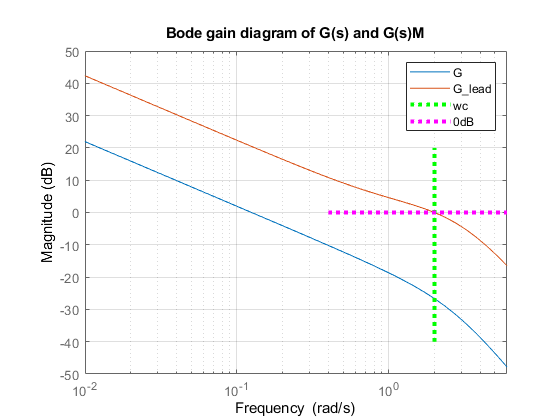


figure; clf
bodemag(G,G*Mlead,{wmin,wmax});grid;hold on
plot([wc,wc],[-40,20],'g:','linewidth',3)
plot([wc/5,wc*5],[0,0],'m:','linewidth',3)
title(['Bode gain diagram of G(s) and G(s)M'])
legend('G','G_lead','wc','0dB')

STEP 5: Recover low frequency gain using the lag component which has a single unknown parameter *p*. Here for simplicity of illustrration we set the gain recovery to be p=5.  Section 4 shows how one could determine this from a specific offset criteria.


$$\;\;\left(\frac{s+\frac{w_c }{10}}{s+\frac{w_c }{10p}}\right)$$


p=gainrecovery

p = 5

Mlag = tf([1,wc/10],[1,wc/(p*10)])

Mlag =
 
  s + 0.2
  --------
  s + 0.04
 
Continuous-time transfer function.



## Check the final design

You should ensure that the phase margins and bandwidth criteria have been met and also that pole/zero ratio is within sensible limits.

If the design is correct, you would expect the compensated system to have:

- A PM similar  to the target PM (likely a few degrees worse due to the negative phase from the lag component).

- A cross over frequency similar to the one specified.

- The phase lift around the cross-over frequency should be evident when one overlays the compensated and uncompensated plots.

- The increase in low frequency gain offered by the lag component will be evident in overlay plots (with and without the lag component), as well as the consequent phase dip well to the left of the cross over frequency.

disp('******************************************************')

******************************************************


disp('CHECK MARGINS OF FINAL DESIGN')

CHECK MARGINS OF FINAL DESIGN


disp(['Target phase margin was ',num2str(desiredPM)])

Target phase margin was 60


disp(['Target cross-over frequency was ',num2str(wc)])

Target cross-over frequency was 2


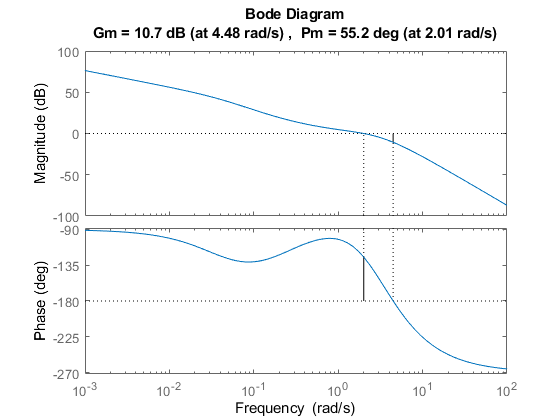

figure; clf
margin(G*Mlead*Mlag)

disp('*****************************************')

*****************************************


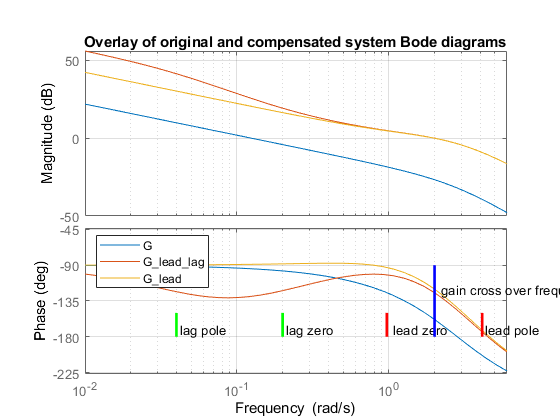

figure; clf
bode(G, G*Mlead*Mlag, G*Mlead,{wmin,wmax});grid; hold on

plot([pole,pole],[-180,-150],'r-','linewidth',2)
text(pole*1.05,-170,'lead pole')
plot([zero,zero],[-180,-150],'r-','linewidth',2)
text(zero*1.1,-170,'lead zero')
plot(wc/(10*p)*[1,1],[-180,-150],'g-','linewidth',2)
text(wc*1.05/(10*p),-170,'lag pole')
plot((wc/10)*[1,1],[-180,-150],'g-','linewidth',2)
text(1.05*wc/10,-170,'lag zero')
plot([wc,wc],[-180,-90],'b-','linewidth',2)
text(wc*1.1,-120,'gain cross over frequency')
legend('G','G_lead_lag','G_lead','Location','Northwest')
title('Overlay of original and compensated system Bode diagrams')


disp('BELOW is SECTION 3')

BELOW is SECTION 3


disp(' ');

## Section 3: Step responses and overlay with lead, lag and lead-lag designs

Step responses are included below for completeness. We have also overlaid this with the alternative of a lag-only design. it is clear that the lag only design is much slower (lower bandwidth), but therefore also uses a much less aggressive input.

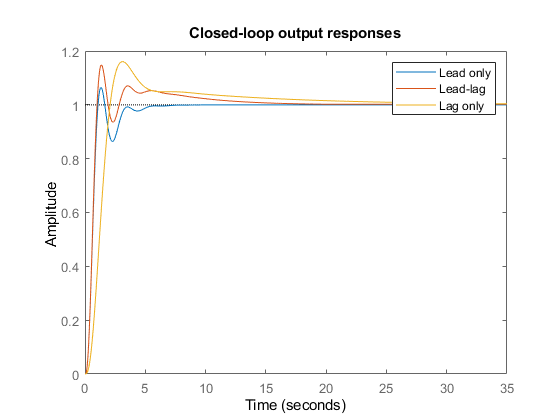

figure;clf
Mlagonly = tf([7.16 0.61],[1,0.015]);  %% see file lag_design_with_bode.mlx for details
GcMlead=feedback(G*Mlead,1);
GcMleadlag=feedback(G*Mlead*Mlag,1);
GcMlagonly=feedback(G*Mlagonly,1);
step(GcMlead,GcMleadlag,GcMlagonly);
title('Closed-loop output responses')
legend('Lead only','Lead-lag','Lag only')

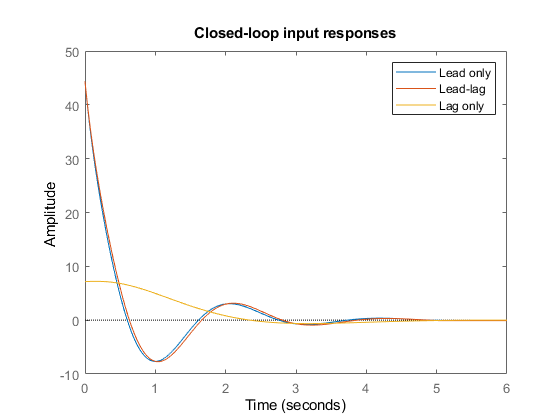


figure;clf
GcMleadu=feedback(Mlead,G);
GcMleadlagu=feedback(Mlead*Mlag,G);
GcMlagonlyu=feedback(Mlagonly,G);
step(GcMleadu,GcMleadlagu,GcMlagonlyu);
title('Closed-loop input responses')
legend('Lead only','Lead-lag','Lag only')



disp('BELOW is SECTION 4')

BELOW is SECTION 4


disp(' ');

### Section 4: Meeting offset criteria more precisely

We know the steady-state gain of the compensator, namely:


$$M\left(s\right)\;=\;\;\;K\;\;\left(\frac{s+\frac{w_c }{10}}{s+\frac{w_c }{10p}}\right)$$

$$\left(\frac{s+\frac{w_c }{\sqrt{r}}}{s+w_c \sqrt{r}}\right)\;\;\;\;\Longrightarrow \;\;\;\;M\left(0\right)=K\frac{p}{r}$$


**Offset to steps**: For a simple fbk loop with system G(s) and compensator M(s) and no integrator, offset to a constant unity reference is given by the formula: $e_{\mathrm{ss}} =\frac{1}{1+G\left(0\right)M\left(0\right)}$=$\frac{r}{r+G\left(0\right)K\;p}$

Hence, given a required offset and *r, K* are known, one can determine the parameter *p*.

**Offset to ramps** can also be useful and is commonly used in books to help create more precise criteria to enable systematic/explicit design.This formula is only useful if the system DOES include an integrator. Offset to a unit ramp is given as:

 $e_{\mathrm{ramp}} =\lim_{s\longrightarrow 0} \frac{1}{\mathrm{sG}\left(s\right)M\left(s\right)}$;                                   Assume that: $\lim_{s\longrightarrow 0} \mathrm{sG}\left(s\right)=\alpha$

$\Longrightarrow \;\;\;\;\;\;$$e_{\mathrm{ramp}} =\frac{r}{\alpha K\;p}$;      

So again,  given a required offset and *r, K* are known, one can determine the parameter *p*.